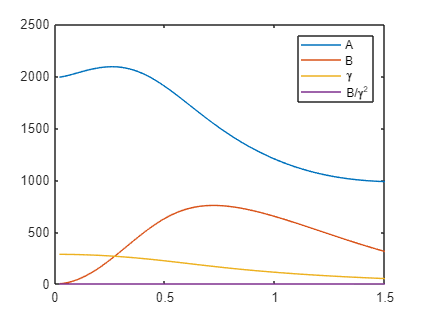

hydro = struct();
hydro = readWAMIT(hydro,'rm3.out',[]); % function from WECSim
w_wamit = hydro.w;
% A = hydro.A(3,3,:);
% A = A(:);
% B = hydro.B(3,3,:);
% B = B(:);
gamma = hydro.ex_ma(3,1,:);
gamma = gamma(:);

draft = 2;

figure
plot(w_wamit,A,w_wamit,B,w_wamit,gamma,w_wamit,B./gamma.^2)
xlim([0 1.5])
legend('A','B','\gamma','B/\gamma^2')